## 看不同方向上的电场强度分布

说明：这里的θ指的是远场观测处与z轴正方向夹角，不论反射还是透射，这里的θ用的是相同定义，对于透射而言，θ是介于pi/2与pi之间的，对于反射而言，θ是介于0和pi/2之间的。

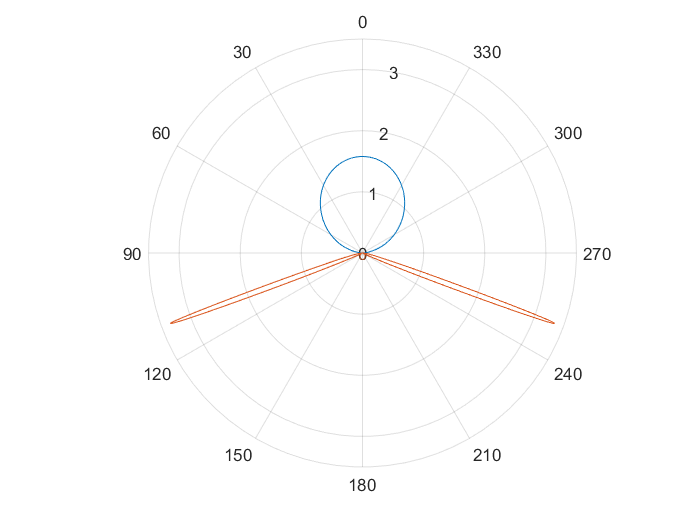

clear
lambda = 670*1e-9;  % 散射光波长
k0 = 2*pi/lambda;   % 真空中波矢
D = [1e9 50 1e9];   % 各层介质厚度，单位nm
n = [1.33 0.13767+3.7917i 1.51];    % 各层介质折射率
n1 = n(1);  % 第一层介质折射率
n2 = n(2);  % 第二层介质折射率
n3 = n(3);  % 第三层介质折射率
H = 10*1e-9;   % 偶极子距离金膜表面距离
h = k0*H;   % 无量纲单位，用来衡量偶极子距离金膜远近，比如h = 2pi表示距离一个波长
phi = 0*pi/2;   % 测量方位角
p = [1 1i 0].';    % 偶极子取向

s = @(theta) [sin(theta)*cos(phi) sin(theta)*sin(phi) cos(theta)].';    % 光线方向矢量
Rs = @(theta) TMMR('s',lambda*1e9,theta,D,n);   % s偏振反射系数
Rp = @(theta) TMMR('p',lambda*1e9,theta,D,n);   % p偏振反射系数
Ts = @(theta) TMMT('s',lambda*1e9,asin(n3*sin(theta)/n(1)),D,n);    % s偏振透射系数
Tp = @(theta) TMMT('p',lambda*1e9,asin(n3*sin(theta)/n(1)),D,n);    % p偏振透射系数

nu1 = @(theta) sqrt(n1^2 - (n3*sin(theta)).^2); % 介质一中纵向有效折射

erho = [cos(phi) sin(phi) 0].'; % 柱坐标中径向基矢，对应p偏振光
ephi = [-sin(phi) cos(phi) 0].';  % 柱坐标中方位角基矢，对应s偏振光
ez = [0 0 1].'; % 柱坐标中z方向基矢
etheta = @(theta) [cos(theta)*cos(phi) cos(theta)*sin(phi) -sin(theta)].';
% 极角对应的基矢

Er = @(theta) exp(-1i*n1*h*cos(theta)) ...
    *(p.'*ephi*ephi + p.'*etheta(theta)*etheta(theta)) ...
    + exp(1i*n1*h*cos(theta)) ...
    * (Rs(theta)*p.'*ephi*ephi - Rp(theta)*(p.'*etheta(theta) + 2*sin(theta)*p.'*ez)*etheta(theta));
% 远场反射光矢量
Et = @(theta) -n3*cos(theta).*exp(1i*h*nu1(theta))./nu1(theta) ...
    .*(Ts(theta)*p.'*ephi*ephi ...
    - Tp(theta)/n1*(nu1(theta)*p.'*erho + n3*sin(theta)*p.'*ez).*etheta(theta));
% 远场透射光矢量
Edp = @(theta) -cross(s(theta),cross(s(theta),p));
% 偶极子在均匀介质中远场电矢量

theta1 = [linspace(0,pi/2,1000) linspace(3*pi/2,2*pi,1000)];
theta2 = linspace(pi/2,3*pi/2,2000);
% theta3 = linspace(0,pi,1000);
for ii = 1:2000
    R(ii) = norm(Er(theta1(ii)));   % 反射场模值
    T(ii) = norm(Et(theta2(ii)));   % 投射场模值
%     D(ii) = norm(Edp(theta3(ii)));
end

figure
polarplot(theta1,R.^2)  
% 平方之后对应能量大小，值与坡印廷矢量之间只差一个常系数，所以没有像文中一样再计算
% 磁场强度，然后计算坡印廷矢量云云
hold on
polarplot(theta2,T.^2)
hold on
% rlim([0 6])
ax = gca;
ax.ThetaZeroLocation = 'top';


% figure
% polarplot(theta3,D.^2)
% ax = gca;
% ax.ThetaZeroLocation = 'top';